s = tf('s'); 
P = 1/(s+3);
sys = ss(P);
A = sys.A, B = sys.B, C = sys.C, D = sys.D,

A = -3

B = 1

C = 1

D = 0

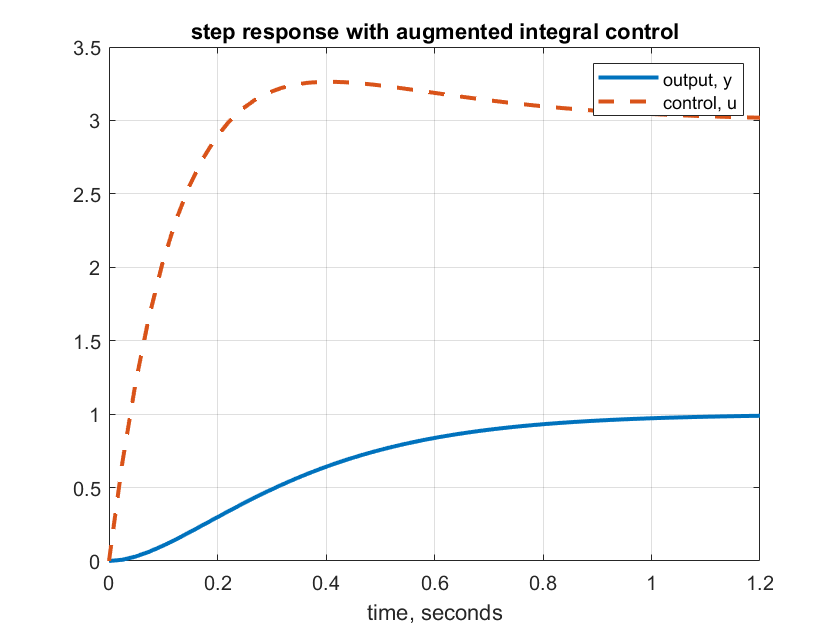


%% (a)
% augmented system matrices

Aaug =  [A 0;C 0];
Baug =  [B; 0];
Caug =  [C 0];
Daug =  0;
% place poles in desired locations
desired_poles =  [-5 -6];
Kaug =  place(Aaug,Baug,desired_poles);

%% (b) and (c)
% simulate response of y and u to a step command
t = linspace(0,1.2,50);

% system matrices for Tyr and Tur, the transfer functions mapping the
% command input r to the output y and the control signal u
Acl = Aaug - Baug * Kaug;
Bcl = [0;-1];
Ycl = Caug; 
Ucl = -Kaug;
Tyr = ss(Acl,Bcl,Ycl,0);
Tur = ss(Acl,Bcl,Ucl,0);

y = step(Tyr,t);
u = step(Tur,t);

figure(1)
clf
plot(t,y,'-',t,u,'--')
xlim([0,t(length(t))])
xlabel('time, seconds')
legend('output, y','control, u')
title('step response with augmented integral control')
grid
set(findall(gcf,'type','line'),'linewidth',2)


TFyr =  tf(Tyr);
'The zero of the system is: ' , tzero(TFyr)

ans = 'The zero of the system is: '


ans =

  0×1 empty double column vector




% add feedforward and see how it affects command response



% % (d)
G = 5; 
Acl = Aaug - Baug * Kaug;
Bcl2 = [G;-1];
Ycl = Caug; 
Ucl = -Kaug;
Tyr2 = ss(Acl,Bcl2,Ycl,0);

TFyr2 =  tf(Tyr2);
'The zero of the new system is: ',tzero(TFyr2)

ans = 'The zero of the new system is: '

ans = -6.0000

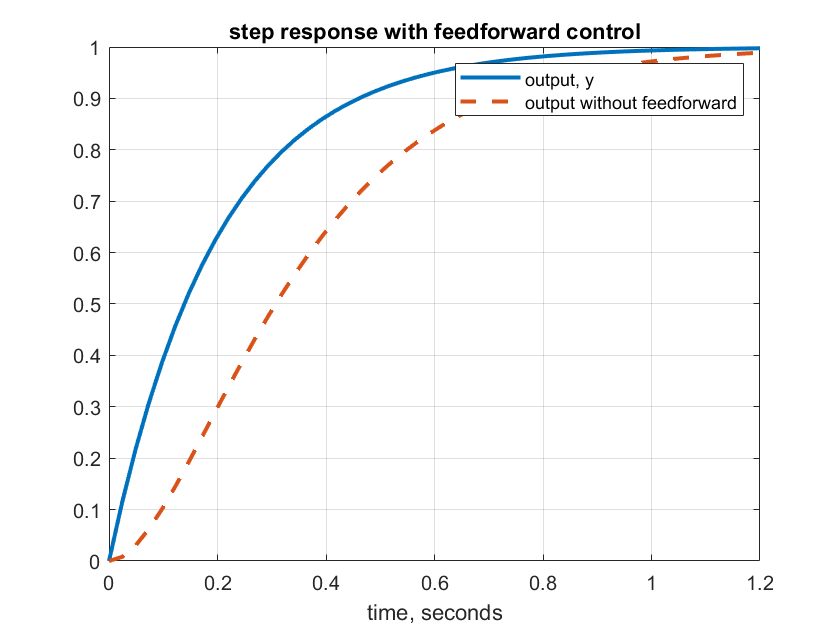

y2 = step(Tyr2,t);

figure(1)
clf
plot(t,y2,'-',t,y,'--')
xlim([0,t(length(t))])
xlabel('time, seconds')
legend('output, y','output without feedforward')
title('step response with feedforward control')
grid
set(findall(gcf,'type','line'),'linewidth',2)

fprintf('Feedforward added a zero and accelerate the command tracking')

feedforward added a zero and accelerate the command tracking